clc
clear all
close all

num_iteration = 10^4;
E_bit = 1; % Energy of Bits
num_bit = 1;

snr_db = [-4:10];
simsnr = 10.^(snr_db/10);
err_prob = zeros(1,length(snr_db));

for i = 1:length(snr_db)
    snr = 10^(snr_db(i)/10);
    err_count = 0;
    
    for iter = 1:num_iteration
        
        bit = round(rand(1, num_bit));
        data = 2*bit - 1;
        
        m = 2;
        omega = 10;
        fading = random('nakagami', m, omega, [1, num_bit]);
%         fading = randraw('nakagami', [m, omega], [1, num_bit]);

%         sigm = 1; % channel variance
%         m = 1.5; % Nakagami-m parameter
%         thta = 0 + (pi-0).*rand(1,num_bit); % uniform phase
%         y = gamrnd(m, sigm/m, 1, num_bit); % amplitude having Gamma distribution
%         fading = sqrt(y).*exp(-1i*thta); % Samples for Nakagami-m distribution
        
        pl_exponent = 2; % for LOS
        freq = 200e06; % MHz
        dist = 20; % meter
        path_loss = ((3e08/(4*pi*freq))^2) * dist^(-pl_exponent);
        
        H = fading * sqrt(path_loss);
%         H = sqrt(.5)*( randn(1) + j.*randn(1)); % Channel Coefficient
        N0 = E_bit/snr;
        noise = randn(1, num_bit); % Noise     
        
%         received = sqrt(snr)*abs(H)*data + (sqrt(.5)*noise);
        received = abs(H).*data + (sqrt(N0/2)*noise);
        detected = received >= 0;
        
%         if ((detected==0 && bit==1)||(detected==1 && bit==0))
%             err_count = err_count + 1;
%         end
        err_count = err_count + sum(xor(detected, bit));
    end
    
    err_prob(i) = err_count/num_iteration;
end

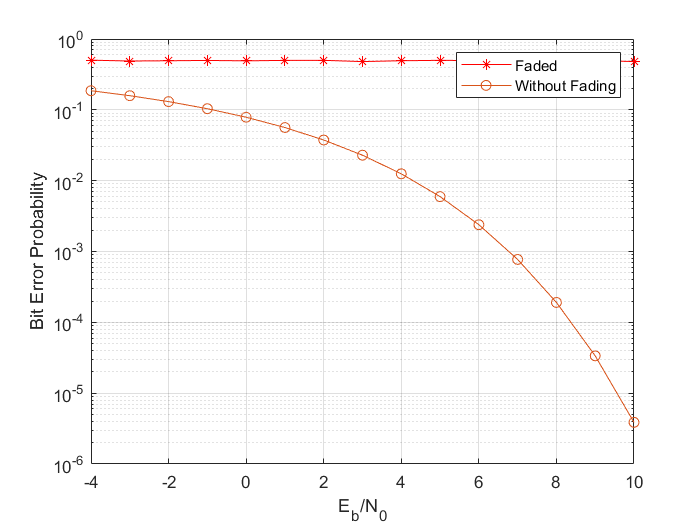

qf = qfunc(sqrt(2.*simsnr));

figure()
semilogy(snr_db,err_prob,'-r*',snr_db,qf,'-o')
% semilogy(snr_db,erpr,'-r*')
xlabel('E_b/N_0'); ylabel('Bit Error Probability')
h = legend('Faded','Without Fading');
set(h,'Interpreter','none')
grid on, hold on